% COnstant
% P = 0.95
tp = 2.26;
kp = 1.96;
C = sqrt(3);
delta_M = 0.002;
delta_f = 50;
Cf = sqrt(3);

t_start = 25.0;
t_end = 25.2;
t = mean([t_start, t_end]);
ps = 3169.0;
H = mean([0.39, 0.38]);
pw = H * ps;

% function
fv = @(t, p, pw, vo) vo*sqrt((1 + t/273.15)*(1+0.3192*pw/p))

fv = function_handle with value:
    @(t,p,pw,vo)vo*sqrt((1+t/273.15)*(1+0.3192*pw/p))


% Data here

% f
fi = [36.604 36.588 36.590 36.580 36.587];

% 干涉法
x_gs = [6.420 6.828 7.302 7.724 8.142 8.686 9.028 9.422 9.842 10.216 10.782 11.216 ];

% 相位比较法
x_xw = [5.502 6.764 8.048 8.744 9.362 10.122 11.272 12.188 13.146 14.124 15.072 15.982];

% Water
x_wt = [1.182 3.346 5.382 7.232 9.206 11.242 13.426 15.624 18.242 20.323];

% 时差法
l_A = [16.802 20.824] .* 10^-2;
t_A = [56 69] .* 10^-6;

l_B = [18.422 22.126] .* 10^-2;
t_B = [114 141] .* 10^-6;

f = mean(fi) * 10^3

f =                    36589.8


% A.1
deltaX = diff(x_gs)

deltaX =                      0.408         0.473999999999999         0.422000000000001         0.417999999999999                     0.544         0.342000000000001                     0.394                      0.42         0.373999999999999         0.566000000000001         0.433999999999999


dx_avg = mean(deltaX)

dx_avg =                      0.436


% lamda = 2 * dx_avg;
ft = fittype('poly1');
xx = (1:1:12)';
fun = fit(xx, x_gs', ft)

fun =      Linear model Poly1:
     fun(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =      0.4319  (0.4224, 0.4414)
       p2 =       5.994  (5.924, 6.064)

lamda = 2 * fun.p1

lamda =           0.86372027972028


v_a = f * lamda * 10^-2

v_a =           316.033522909091



sa = std(deltaX)

sa =         0.0678350941622404


ua = sa / sqrt(12-1)

ua =         0.0204530504504163


Ux = sqrt((tp * ua)^2 + (kp * delta_M/C)^2)

Ux =          0.046279266540376


U_Lamda = 2 * Ux

U_Lamda =          0.092558533080752



fa = std(fi)

fa =        0.00878635305459538


f_ua = fa / sqrt(5 - 1) * 1000

f_ua =           4.39317652729769


Uf = sqrt((tp*f_ua)^2 + (kp * delta_f/Cf)^2)

Uf =           57.4448432266407



U = v_a*sqrt((U_Lamda/lamda)^2 + (Uf/f)^2)

U =           33.8706164184407


va = fv(t, ps, pw, v_a)

va =           349.938535520888


% A.2
x_xw = x_xw';
deltaX = diff(x_xw)

deltaX =                      1.262
                     1.284
                     0.696
                     0.618
                      0.76
                      1.15
                     0.916
                     0.958
                     0.978
         0.947999999999999


dx_avg = mean(deltaX)

dx_avg =          0.952727272727273


% lamda = 2 * dx_avg;
ft = fittype('poly1');
xx = (1:1:12)';
fun = fit(xx, x_xw, ft)

fun =      Linear model Poly1:
     fun(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =      0.9239  (0.8868, 0.9609)
       p2 =       4.855  (4.582, 5.128)

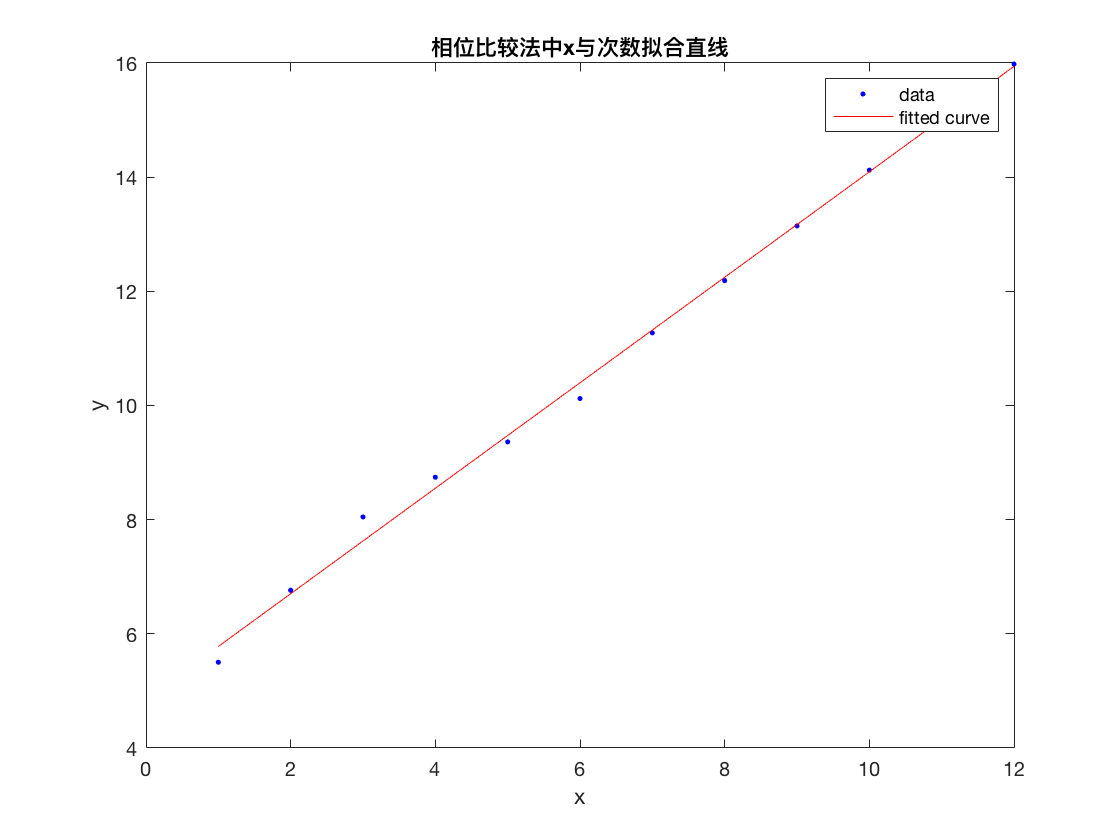

plot(fun,xx,x_xw )
title('相位比较法中x与次数拟合直线')

lamda = 2 * fun.p1

lamda =           1.84770629370629


v_b = f * lamda * 10^-2

v_b =           676.072037454545



sa = std(deltaX)

sa =          0.215236191617066


length = size(x_gs);
ua = sa / sqrt(11-1)

ua =         0.0680636600410367


Ux = sqrt((tp * ua)^2 + (kp * delta_M/C)^2)

Ux =          0.153840520136532


U_Lamda = 2 * Ux

U_Lamda =          0.307681040273065



fa = std(fi)

fa =        0.00878635305459538


f_ua = fa / sqrt(5 - 1) * 1000

f_ua =           4.39317652729769


Uf = sqrt((tp*f_ua)^2 + (kp * delta_f/Cf)^2)

Uf =           57.4448432266407



U = v_b*sqrt((U_Lamda/lamda)^2 + (Uf/f)^2)

U =           112.584880700699


va = fv(t, ps, pw, v_b)

va =            748.60304854913


% A.3 
x_wt= x_wt';
deltaX = diff(x_wt)

deltaX =                      2.164
                     2.036
                      1.85
                     1.974
                     2.036
                     2.184
                     2.198
                     2.618
                     2.081


dx_avg = mean(deltaX)

dx_avg =           2.12677777777778


% lamda = 2 * dx_avg;
ft = fittype('poly1');
xx = (1:1:10)';
fun = fit(xx, x_wt, ft)

fun =      Linear model Poly1:
     fun(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =       2.111  (2.043, 2.18)
       p2 =      -1.092  (-1.518, -0.6656)

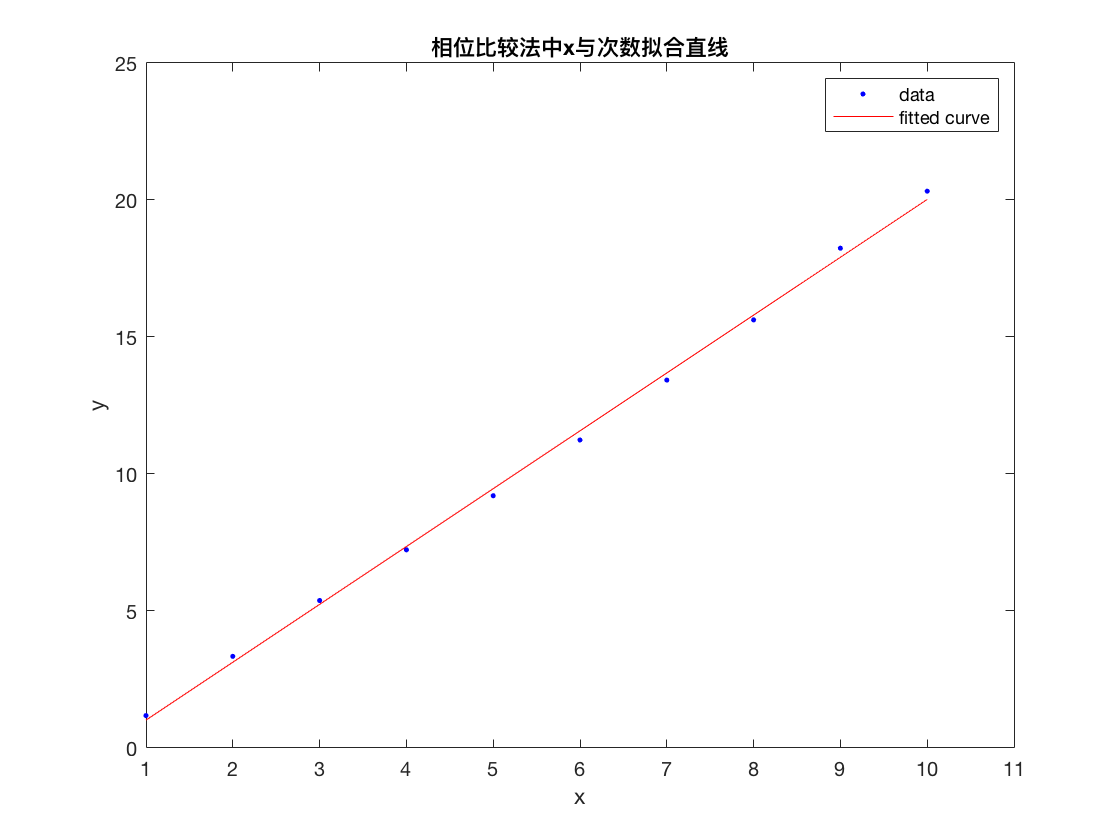

plot(fun,xx,x_wt )
title('相位比较法中x与次数拟合直线')

lamda = 2 * fun.p1

lamda =           4.22265454545455


v_c = f * lamda * 10^-2

v_c =           1545.06085287273



sa = std(deltaX)

sa =          0.214928928821702


length = size(x_gs);
ua = sa / sqrt(9-1)

ua =         0.0759888515214933


Ux = sqrt((tp * ua)^2 + (kp * delta_M/C)^2)

Ux =          0.171749716706866


U_Lamda = 2 * Ux

U_Lamda =          0.343499433413733



fa = std(fi);
length = size(fi);
f_ua = fa / sqrt(5 - 1) * 1000

f_ua =           4.39317652729769


Uf = sqrt((tp*f_ua)^2 + (kp * delta_f/Cf)^2)

Uf =           57.4448432266407



U = v_c*sqrt((U_Lamda/lamda)^2 + (Uf/f)^2)

U =           125.709161121928


va = fv(t, ps, pw, v_c)

va =           1710.81955853293


% A.4
% Material 1
vvecA = l_A ./ t_A

vvecA =           3000.35714285714          3017.97101449275


v_bA = mean(vvecA)

v_bA =           3009.16407867495



vvecB = l_B ./ t_B

vvecB =            1615.9649122807          1569.21985815603


v_bB = mean(vvecB)

v_bB =           1592.59238521837
